clc; clearvars; close all;

%% ------------------------------------------------------------------------
% Paths
project_root = './';
addpath(fullfile(project_root, 'dynamics_library'));
addpath(fullfile(project_root, 'data'));

%% ------------------------------------------------------------------------
% Load physical & motion parameters
[phys, move] = mm_params_build_save_load('load', 'mm_params');

Loaded: mm_params.mat


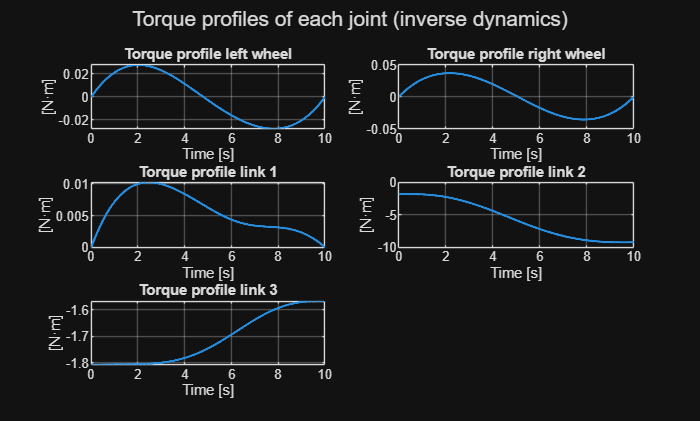

r = phys.r;
L = phys.L;

%% ------------------------------------------------------------------------
% Initial joint configuration from move.si
th_r0 = move.si.right_wheel_m.initial;   % right wheel angle [rad]
th_l0 = move.si.left_wheel_m.initial;    % left wheel angle [rad]
th10  = move.si.link1_rad.initial;       % link 1 joint [rad]
th20  = move.si.link2_rad.initial;       % link 2 joint [rad]
th30  = move.si.link3_rad.initial;       % link 3 joint [rad]

% Base pose initial conditions (free orientation)
x_m0     = 0;    % [m]
y_m0     = 0;    % [m]
theta_m0 = 0;    % [rad]

% Generalized coordinates:
% q = [x_m; y_m; theta_m; theta_r; theta_l; theta_1; theta_2; theta_3]
q0 = [x_m0;
      y_m0;
      theta_m0;
      th_r0;
      th_l0;
      th10;
      th20;
      th30];

%% ------------------------------------------------------------------------
% Desired final values (tune these to match paper trajectory)
T = 10;                      % total motion time [s]

th_rT = th_r0 + 2*pi;        % one wheel revolution (example)
th_lT = th_l0 + 2*pi;
th1T  = th10  + deg2rad(20);
th2T  = th20  + deg2rad(40);
th3T  = th30  + deg2rad(-10);

%% 5th-order polynomial trajectory: pos, vel, acc between q0 -> qT over [0,T]
poly5 = @(t, T, q0, qT) deal( ...
    q0 + (10*(t/T).^3 - 15*(t/T).^4 + 6*(t/T).^5) .* (qT - q0), ...
    (30*(t.^2)/T^3 - 60*(t.^3)/T^4 + 30*(t.^4)/T^5) .* (qT - q0), ...
    (60*t/T^3 - 180*(t.^2)/T^4 + 120*(t.^3)/T^5) .* (qT - q0) );

%% ------------------------------------------------------------------------
% Time grid
N  = 1001;
tt = linspace(0, T, N);
dt = tt(2) - tt(1);

%% Preallocate histories
q_hist    = zeros(8, N);   % generalized coordinates
eta_hist  = zeros(5, N);   % independent velocities
etad_hist = zeros(5, N);   % independent accelerations
u_hist    = zeros(5, N);   % actuator torques

% Set initial configuration
q_hist(:,1) = q0;

%% ------------------------------------------------------------------------
% Main loop: generate trajectory + inverse dynamics torques
for k = 1:N
    t = tt(k);

    % --- Desired joint trajectories (independent coordinates) ---
    [th_r, th_r_dot, th_r_ddot] = poly5(t, T, th_r0, th_rT);
    [th_l, th_l_dot, th_l_ddot] = poly5(t, T, th_l0, th_lT);
    [th1,  th1_dot,  th1_ddot ] = poly5(t, T, th10,  th1T);
    [th2,  th2_dot,  th2_ddot ] = poly5(t, T, th20,  th2T);
    [th3,  th3_dot,  th3_ddot ] = poly5(t, T, th30,  th3T);

    % Independent velocities (eta) and accelerations (eta_dot)
    eta     = [th_r_dot; th_l_dot; th1_dot; th2_dot; th3_dot];
    eta_dot = [th_r_ddot; th_l_ddot; th1_ddot; th2_ddot; th3_ddot];

    if k > 1
        % --- Integrate base pose forward with nonholonomic mapping ---
        q_prev   = q_hist(:,k-1);
        R_prev   = mm_R_fun(q_prev);         % [8x5]
        qdot_prev= R_prev * eta_hist(:,k-1); % full q_dot from previous eta
        q_hist(:,k) = q_prev + qdot_prev * dt;

        % Override joint coordinates with desired (to avoid drift)
        q_hist(4:8,k) = [th_r; th_l; th1; th2; th3];
    else
        % at k=1: ensure joints match desired
        q_hist(4:8,1) = [th_r; th_l; th1; th2; th3];
    end

    % Current state for dynamics
    qk = q_hist(:,k);

    % --- Reduced dynamics matrices at qk ---
    M1 = mm_M1_fun(qk);          % [5x5]
    Rk = mm_R_fun(qk);           % [8x5]
    qdot = Rk * eta;             % [8x1]
    C1 = mm_C1_fun(qk, qdot);    % [5x5]
    G1 = mm_G1_fun(qk);          % [5x1]
    B1 = mm_B1_fun(qk);          % [5x5]

    % --- Inverse dynamics: u = B1^{-1}(M1*eta_dot + C1*eta + G1) ---
    u = B1 \ (M1*eta_dot + C1*eta + G1);

    % Store histories
    eta_hist(:,k)   = eta;
    etad_hist(:,k)  = eta_dot;
    u_hist(:,k)     = u;
end

%% ------------------------------------------------------------------------
% Plot torque profiles (similar structure to paper's figures)

figure;

subplot(3,2,1);
plot(tt, u_hist(2,:), 'LineWidth', 1.4);
title('Torque profile left wheel');
ylabel('[N·m]'); xlabel('Time [s]'); grid on;

subplot(3,2,2);
plot(tt, u_hist(1,:), 'LineWidth', 1.4);
title('Torque profile right wheel');
ylabel('[N·m]'); xlabel('Time [s]'); grid on;

subplot(3,2,3);
plot(tt, u_hist(3,:), 'LineWidth', 1.4);
title('Torque profile link 1');
ylabel('[N·m]'); xlabel('Time [s]'); grid on;

subplot(3,2,4);
plot(tt, u_hist(4,:), 'LineWidth', 1.4);
title('Torque profile link 2');
ylabel('[N·m]'); xlabel('Time [s]'); grid on;

subplot(3,2,5);
plot(tt, u_hist(5,:), 'LineWidth', 1.4);
title('Torque profile link 3');
ylabel('[N·m]'); xlabel('Time [s]'); grid on;

sgtitle('Torque profiles of each joint (inverse dynamics)');